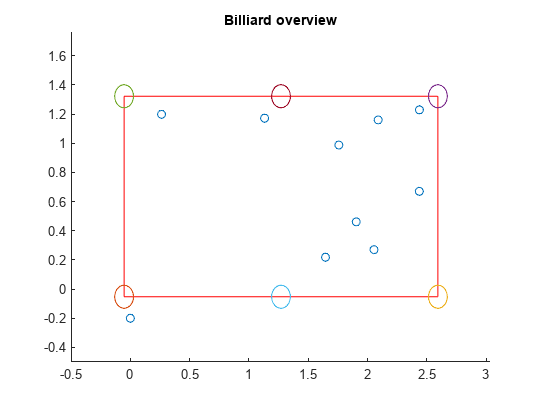

clear all
clc
clf
format long g

counter = 0; % To position the balls which goes into the holes next to each other

% Parameters
u = 5000; % N
m = 0.220; % kg
g = 9.82;
my = 0.55;
r = 0.0525;
theta = 0.02; % Radianer från gammal rapport är 0.01

% Billiard table
width = 2.54;
height = 1.27;
hold on
drawBilliardTable(width, height, r)

% Initial conditions
p(1,1,1) = 1;
p(2,1,1) = 0.6;

% p(1,1,2) = 1/3*width;
% p(2,1,2) = height*2/3;
% 
% p(1,1,3) = 2/3*width;
% % p(2,1,3) = height/2;

%p = billiardSetup(p, width, height, r, size(p,3));
 p = randomBalls(10, p, width, height, r);

v = zeros(2,1,size(p,3));

tau = zeros(1,size(p,3));
tau(1) = pi / 180 * (5); % Radians

Friction = zeros(1,size(p,3));
Friction(1) = m * g * my; % N

initialVelocity = zeros(1,size(p,3));

% Loop variables and euler step
tf = 1; % Seconds to runt the simulation
h = 0.01;
i = 1;

% Initial force on the ball with angle tau
F = zeros(2,tf / h + 1,size(p,3));
F(1,1,1) = u * cos(tau(1)); % x force
F(2,1,1) = u * sin(tau(1)); % y force

for t = h:h:tf
    for n = 1:1:size(p,3)
        % Test if ball is outside playarea, then mirror velocity in that axis
        % and compensate for energy loss        
        [p(1:2,i,n), v(1:2,i,n), tau(n),Friction(n),counter] = edgeDetection(p(1:2,i,n), p(1:2,max(i-1,1),n), v(1:2,i,n), tau(n), width, height,r,Friction(n),counter);
        
        for k = n+1:1:size(p,3)
            if norm(p(1:2,i,k)-p(1:2,i,n)) <= 2 * r && n ~= k && i ~= 1
                v1 = v(1:2,i,n);
                v2 = v(1:2,i,k);
                
                % Calculate the velocities after ball collision
                [v(1:2,i,n), v(1:2,i,k), p(1:2,i,n), p(1:2,i,k), tau(n), tau(k)] = ballCollision(v1,v2,p(1:2,i,n),p(1:2,i,k),p(1:2,i-1,n),p(1:2,i-1,k));                
                
                if norm(v2) == 0
                    initialVelocity(k) = norm(v(1:2,i,k));
                    Friction(k) = m*g*my;
                elseif norm(v1) == 0
                    initialVelocity(n) = norm(v(1:2,i,n));
                    Friction(n) = m*g*my;
                end
            end
        end
        
        % Evaluate next iteration of values according to euler method
        [v(1:2,i+1,n), p(1:2,i+1,n), Friction(n)] = euler2(v(1:2,i,n), p(1:2,i,n), F(1:2,i,n), Friction(n), tau(n), m, h);
        
        % Save the initial velocity of the first ball
        if i == 1
            initialVelocity(n) = norm(v(1:2,i+1,n));
        end
        
        % Check for rolling or sliding
        if norm(v(1:2,i+1,n)) < 5/7 * initialVelocity(n) && norm(v(1:2,i+1,n)) ~= 0 % Rolling and test if velocity is zero, then no friction shall be added
            Friction(n) = 5/7 * m * g * theta;
        elseif norm(v(1:2,i+1,n)) > 5/7 * initialVelocity(n) % Sliding
            Friction(n) = m * g * my;
        end
        
        
    end
    
    i = i + 1;
    if sum(v(:,i,:)) == 0
        break;
    end
end

plotBilliard(p,width,height)


%plotVelocity(v,h,tf)

## Buggar


% Bollar stannar ibland när de krockar?

% Bollar fastnar i varandra, kanske fixat

% Just nu helt elastisk mellan bollar, borde vi ha inelastisk (laggt till
% möjlighet att ändra)


























